clear all 
clc

Загружаем данные из фала

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t1", "v1", "t2", "v2"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Miror = readtable("зеркало комп 1.txt", opts);
TestMom = readtable("тест5мН.txt", opts);
Scan  = readtable("скан 1 комп.txt", opts);
%% Clear temporary variables
clear opts

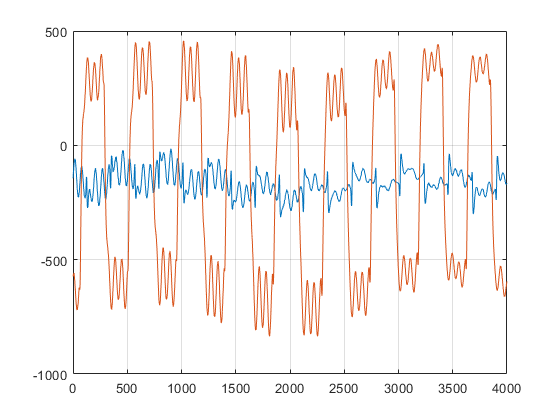

i = 4000;

TestMomV = (TestMom.v2(1494:i+1493))+168;
MirorV = (Miror.v2(234:i+233));
ScanV = (Scan.v2(234:i+233));



figure
plot(ScanV)
grid on
hold on
plot(MirorV)

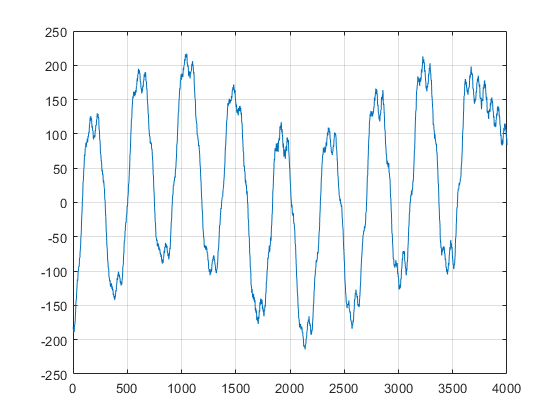



figure
plot(TestMomV)
grid on

Обработка измерений тестового маховика

nt = 444 %Период тестового воздействия

nt = 444

m_test = zeros(nt,10);
m_test(:,1) = TestMomV(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    m_test(:,i) = TestMomV(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

Index exceeds the number of array elements (4000).

sum_m_test = sum(m_test, 2)

figure
plot(sum_m_test);


figure
plot(m_test)
hold off


%Производная скорости
m_test_dt = diff(m_test);
figure
plot(m_test_dt)

